## Population Balance Equations: Quadrature Method of Moments (QMoM)

#### Diffusion controlled growth (for spherical particles with initial radius $r_0 <1\mu m$)


$$\frac{\partial f}{\partial t}+\frac{\partial }{\partial r}\left(\dot{R} f\right)=0$$


initial conditions: $f\left(r,t=0\right)=f^0 \left(r\right)$

boundary conditions: $\dot{R} f\left(r=0,t\right)=0$, $\dot{R} f\left(r=+\infty ,t\right)=0$ 

#### Initial solution


$$f^0 \left(r\right)={\textrm{ar}}^2 \exp \left(-\textrm{br}\right)$$


#### Analytical Solution


$$f\left(r,t\right)=$$

$$\frac{r}{\sqrt{r^2 -2k_G t}}f^0 \left(\sqrt{r^2 -2k_G t}\right)$$


**Growth rate**


$$\dot{R} =\frac{\textrm{dr}}{\textrm{dt}}=\frac{k_G }{r}$$


**Parameters**


$$\begin{array}{l}
a=0\ldotp 108\;\mu m^{-1} {\textrm{cm}}^{-3} \\
b=0\ldotp 60\;\mu m^{-1} \\
k_G =0\ldotp 78\;\mu m^2 s^{-1} 
\end{array}$$


% a and b: distribution parameters
a = 0.108;  % (1/mum/cm3)
b = 0.60;   % (1/mum)

% Growth rate: dr/dt
kG = 0.78;  % growth rate constant (mum2/s)

## Numerical Solution (Quadrature Method of Moments)

% Number of quadrature points
N = 3;

% Domain of integration
rMax = 30;  % maximum radius (mum)
tf = 20;    % maximum time (s)

% Initial distribution (#/cm3/mum)
r = 0:rMax/1000:rMax;
fIn = fInitial(r, a, b);

#### Initial moments and normalization


$$\mu_k =\int_0^{r_{\max } } r^k f^0 \left(r\right)\textrm{dr}$$



$$\mu_k^{\textrm{norm}} =\frac{\mu_k }{\mu_0 }$$


% Initial moments
Neq = 2*N;  % number of moments/equations
muIn = zeros(Neq,1);
for i=0:Neq-1
    muIn(i+1) = AnalyticalMoments(i, r, 0, kG, a, b);
end

% Normalization
muNormIn = muIn/muIn(1);

#### Numerical solution of moment equations


$$\frac{d\mu_k }{\textrm{dt}}=k\sum_{i=1}^N \dot{R_i } {\;r}_i^{k-1} w_i$$


% Solution of moment equations
[t, muNorm] = ode15s(@ODESystem, 0:0.25:tf, muNormIn, [], kG);

% Denormalization
mu = muNorm*muIn(1);

#### Plotting temporal evolution of moments

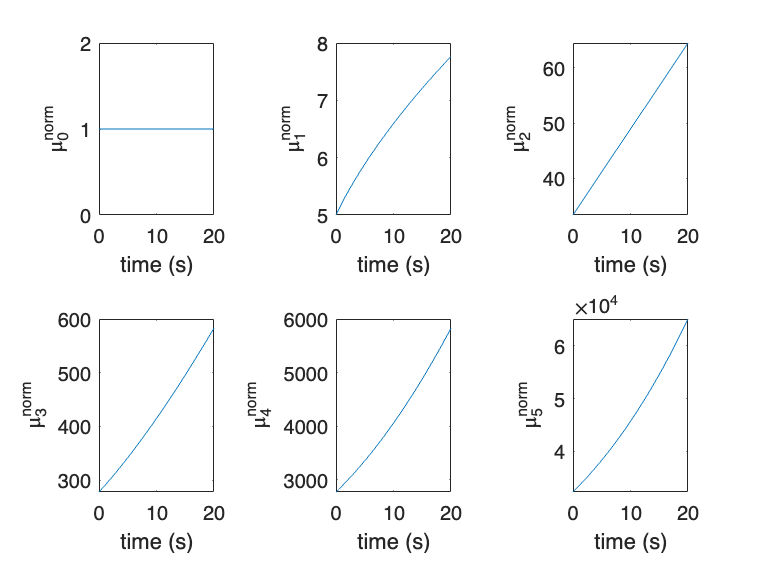

figure;
tiledlayout(2,3);
nexttile; plot(t, muNorm(:,1)); xlabel('time (s)'); ylabel('\mu_0^{norm}');
nexttile; plot(t, muNorm(:,2)); xlabel('time (s)'); ylabel('\mu_1^{norm}');
nexttile; plot(t, muNorm(:,3)); xlabel('time (s)'); ylabel('\mu_2^{norm}');
nexttile; plot(t, muNorm(:,4)); xlabel('time (s)'); ylabel('\mu_3^{norm}');
nexttile; plot(t, muNorm(:,5)); xlabel('time (s)'); ylabel('\mu_4^{norm}');
nexttile; plot(t, muNorm(:,6)); xlabel('time (s)'); ylabel('\mu_5^{norm}');

#### Evolution of mean radius

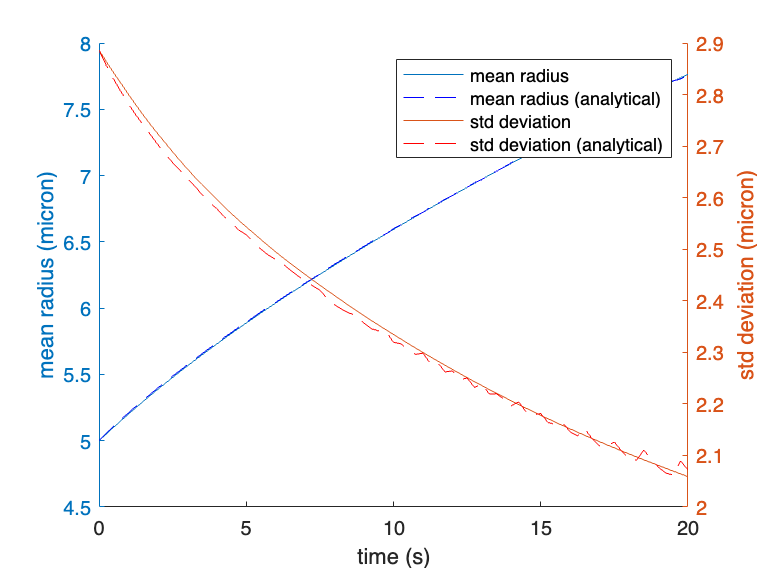

% Analytical results
for k=1:length(t)
    muAnalytical1(k) = AnalyticalMoments(1, r, t(k), kG, a, b);
    muAnalytical2(k) = AnalyticalMoments(2, r, t(k), kG, a, b);
end

figure; hold on;
yyaxis left; ylabel('mean radius (micron)');
plot(t, muNorm(:,2)); 
plot(t, muAnalytical1/muIn(1), 'b--');
yyaxis right; ylabel('std deviation (micron)');
plot(t, sqrt(muNorm(:,3)-muNorm(:,2).^2)); 
plot(t, sqrt(muAnalytical2-muAnalytical1.^2), 'r--');
xlabel('time (s)'); hold off;
legend('mean radius', 'mean radius (analytical)', 'std deviation', 'std deviation (analytical)');

### Plot density functions

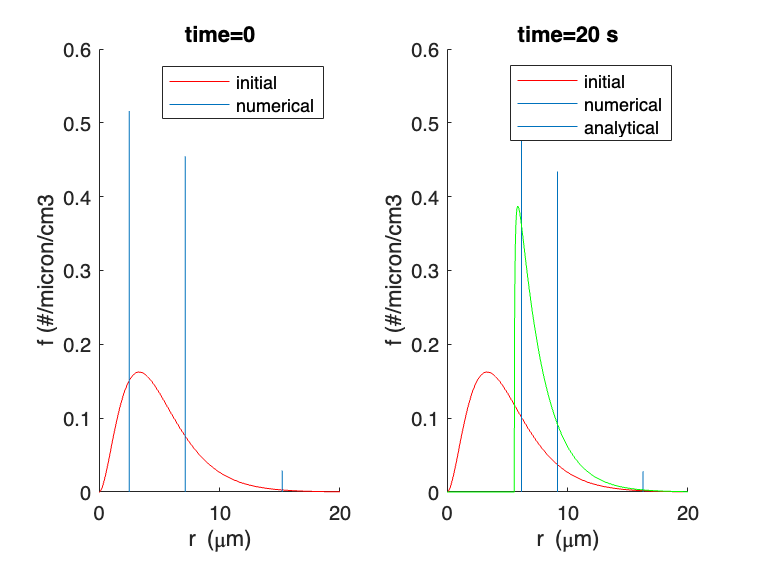

% Plot the distribution function
figure;
tiledlayout(1,2);

% Initial time
nexttile; hold on; xlabel('r (\mum)'); ylabel('f (#/micron/cm3'); title('time=0'); xlim([0 20]);
plot(r, fIn, 'r');
[w, L] = MomentInversion(muNorm(1, :));
for i=1:N
    line([L(i),L(i)], [0 w(i)*muIn(1)]);
end
legend('initial', 'numerical');
hold off;

% Final time
nexttile; hold on; xlabel('r (\mum)'); ylabel('f (#/micron/cm3'); title('time=20 s'); xlim([0 20]);
plot(r, fIn, 'r');
[w, L] = MomentInversion(muNorm(end, :));
for i=1:N
    line([L(i),L(i)], [0 w(i)*muIn(1)]);
end
plot(r, fAnalytical(r, tf, kG, a, b), 'g');
legend('initial', 'numerical','analytical');
hold off;

[w, L] = MomentInversion(muNorm(1, :));
fprintf('Time=0 s: rm(micron)=%f sigma(micron)=%f\n', Lm(w,L), StdDev(w,L));

Time=0 s: rm(micron)=4.999926 sigma(micron)=2.886409



[w, L] = MomentInversion(muNorm(end, :));
fprintf('Time=20 s: rm(micron)=%f sigma(micron)=%f\n', Lm(w,L), StdDev(w,L));

Time=20 s: rm(micron)=7.764768 sigma(micron)=2.058881


## Dynamic evolution of the density function

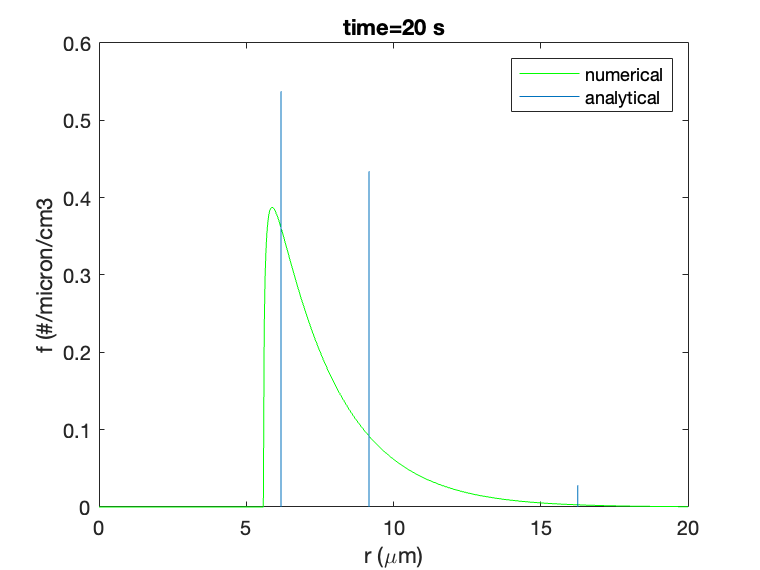

video_name = 'qmom.mp4';
videompg4 = VideoWriter(video_name, 'MPEG-4');
open(videompg4);

figure;
for k=1:length(t)
     
     [w, L] = MomentInversion(muNorm(k, :));

     hold off;
     plot(r, fAnalytical(r, t(k), kG, a, b), 'g');
     hold on;
     for i=1:N
         line([L(i),L(i)], [0 w(i)*muIn(1)]);
     end
     hold on;
     xlabel('r (\mum)'); ylabel('f (#/micron/cm3'); title('time=20 s');
     legend('numerical','analytical');
     xlim([0 20]); ylim([0 0.6]);
     frame = getframe(gcf);
     writeVideo(videompg4, frame);
end

close(videompg4);

## Functions

function dmuNorm = ODESystem(~, muNorm, kG)

    Neq = length(muNorm);
    N = Neq/2;

    [w,L] = MomentInversion(muNorm);

    dmuNorm = zeros(Neq, 1);

    for i=1:Neq
        k = i-1;
        sum = 0;
        for j=1:N
            sum = sum + L(j)^(k-1)*Rdot(kG, L(j))*w(j);
        end
        dmuNorm(i) = k*sum;
    end

end


%% Growth rate
function drdt = Rdot(kG, r)

    drdt = kG/r;

end

%% Moment inversion function (PD algorithm, Gordon 1968)
function [w, L] = MomentInversion(muNorm)

    N = length(muNorm)/2;

    P = zeros(2*N+1, 2*N+1);
    P(1,1) = 1;
    P(1,2) = 1;
    for i=2:2*N
        P(i,2) = (-1)^(i-1)*muNorm(i-1+1);
    end
    
    for j=3:2*N+1
        for i=1:2*N+2-j
            P(i,j) = P(1,j-1)*P(i+1,j-2)-P(1,j-2)*P(i+1,j-1);
        end
    end

    alpha = zeros(2*N,1);
    alpha(1) = 0;
    for i=2:2*N
        alpha(i) = P(1,i+1)/P(1,i)/P(1,i-1);
    end
    
    a = zeros(N,1);
    for i=1:N
        a(i) = alpha(2*i)+alpha(2*i-1);
    end
    
    b = zeros(N-1,1);
    for i=1:N-1
        b(i) = sqrt(alpha(2*i+1)*alpha(2*i));
    end

    A = diag(a);
    for i=1:N-1
        A(i,i+1) = b(i);
        A(i+1,i) = b(i);
    end

    [V,csi] = eig(A);
    L = diag(csi);

    w = zeros(N,1);
    for i=1:N
        w(i) = V(1,i)^2;
    end

end

function f = fInitial(r, a, b)

    f = a*(r.^2).*exp(-b*r);

end

function f = fAnalytical(r, t, kG, a, b)

    f = zeros(length(r),1);
    for i=1:length(r)
        arg = r(i)^2-2*kG*t;
        if (arg > 0)
            f(i) = r(i)/sqrt(arg).*fInitial(sqrt(arg), a, b);
        end
    end

end

%% Mean value
function m = Lm(w,L)

    m = dot(w,L);

end

%% Standard deviation
function sigma = StdDev(w,L)

    m = Lm(w,L);
    sigma = sqrt( dot(w, L.^2) - m^2);

end

%% Moments of the analytical solution
function muk = AnalyticalMoments(k, r, t, kG, a, b)

    muk = 0.;
    for j=1:length(r)-1
        deltar = r(j+1)-r(j);
        Ic = 0.50*(r(j+1)^(k)*fAnalytical(r(j+1), t, kG, a, b)+r(j)^(k)*fAnalytical(r(j), t, kG, a, b));
        muk = muk + Ic*deltar;
    end

end